## **The plane equation**

We have the following equation for a plane:


$$\mathbf{x}^{T}\mathbf{\beta} + \beta_{0} = 0$$


This defines a plane where the vector $\mathbf{\beta}$ is perpendicular to the plane.

**Example in 3 dimensions:**

if $\mathbf{x} = [x\ y\ z]$ are input variables and $\mathbf{\beta} = [a_{x}\ a_{y}\ a_{z}]$ then the above equation is equivalent to $a_{x}x + a_{y}y + a_{z}z + \beta _{0} = 0$. For every value of x and y we can define a z that satisfies the above equation. 

Rearranging in terms of z, we get


$$z  =  -\frac{\left(a_{x}x + a_{y}y + \beta _{0} \right)}{a_{z}}$$


Below is an example to visualize this

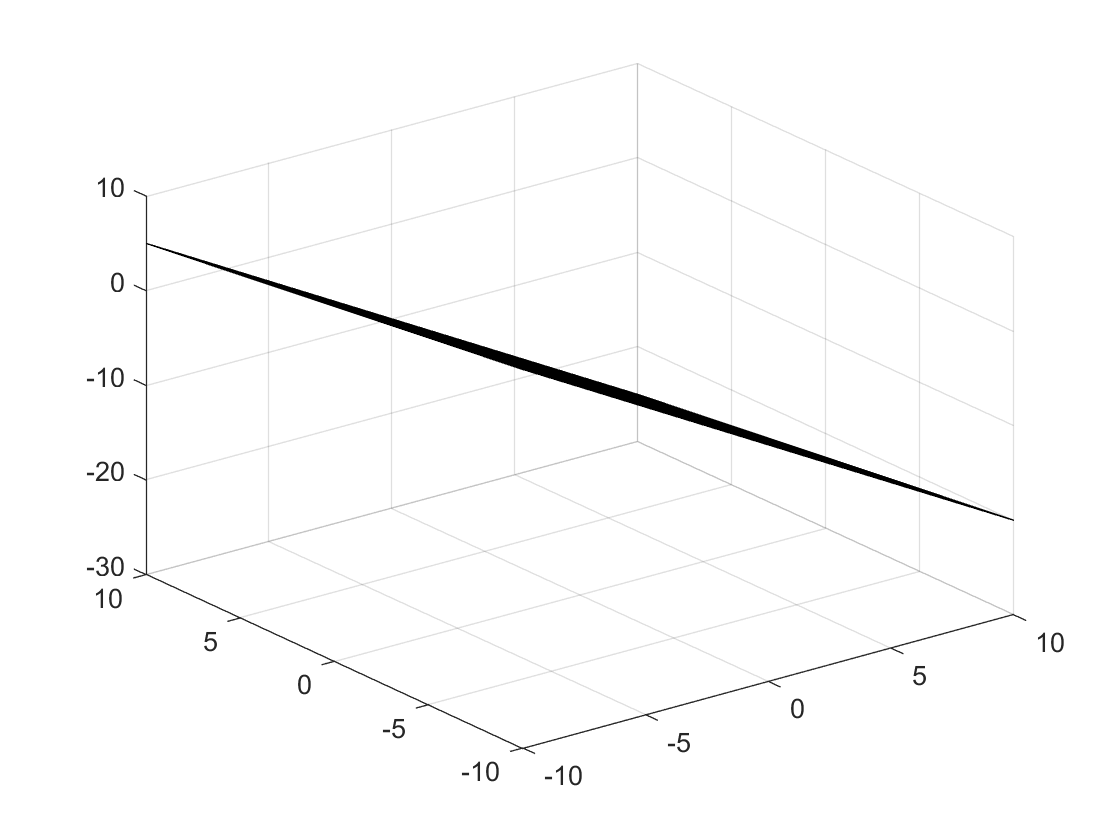

beta = [3 1/2 2]; % This is a vector that is normal to the plane
beta_0 = 15; % This shifts the plane up or down

% Define a meshgrid of x and y values
[x,y] = meshgrid(-10:1:10);

% Solve the plane equation for z
z = -(beta(1).*x + beta(2).*y + beta_0)./beta(3);

% Plot this plane
surf(x,y,z);

So we can plot a plane by writing the equation in terms of z and solving at each point.

Now let's show that the $\mathbf{\beta}$ vector is orthogonal to the plane. We first generate a unit vector of $\mathbf{\beta}$ in the usual way, $\mathbf{\hat{\beta}} = \frac{\mathbf{\beta}}{|\mathbf{\beta}|}$ . If we want to plot a vector from the origin to the plane in the shortest distance possible, it should run parallel to $\mathbf{\hat{\beta}}$, as this vector is normal to the plane.

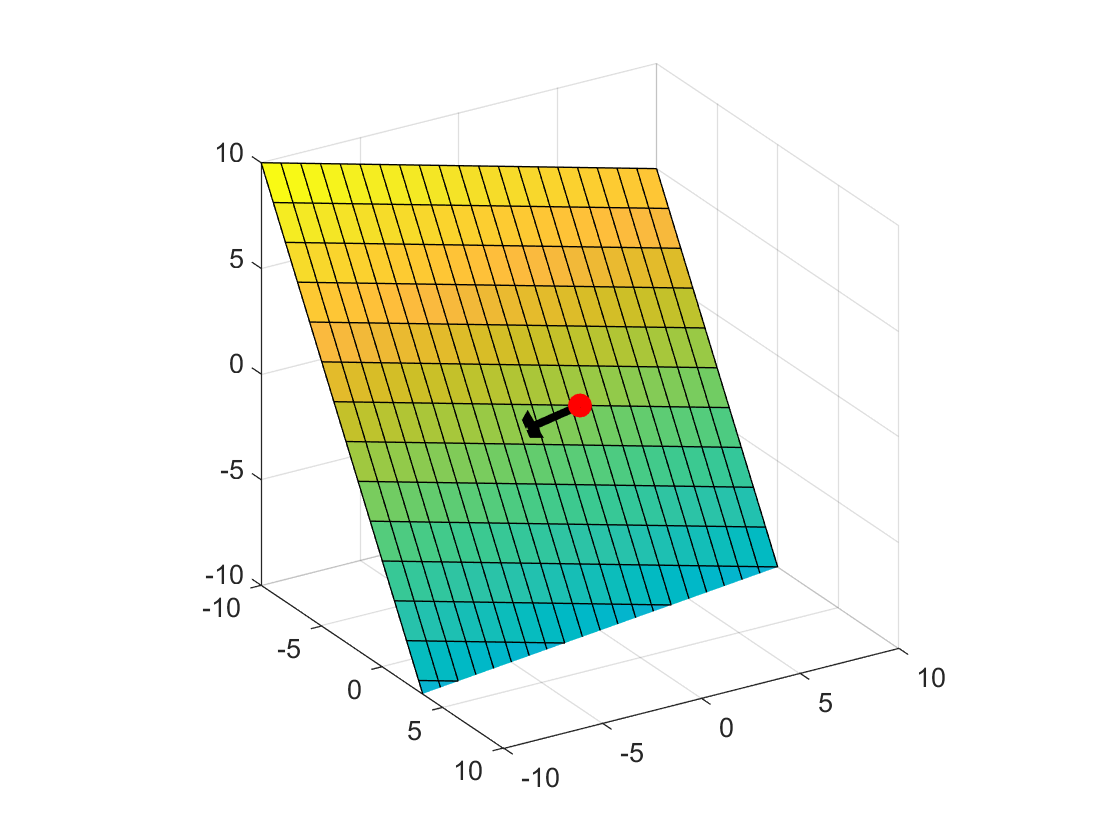

beta_unit_vector = beta./norm(beta);
d = -beta_0/norm(beta);
beta_vector = beta_unit_vector.*d;

% Plot
hold on
plot3(0, 0, 0,'ro-',"MarkerFaceColor","r",'LineWidth',3)
plot3(beta_vector(:,1), beta_vector(:,2), beta_vector(:,3),'k^-','LineWidth',3)
plot3([0 beta_vector(:,1)], [0 beta_vector(:,2)], [0 beta_vector(:,3)],'k-','LineWidth',3)

% Set the plot to be a perfect cube
xlim([-10 10])
ylim([-10 10])
zlim([-10 10])
daspect([1 1 1])
view([58.5 24.3])

What if we want to find the shortest distance between any point x and the plane?